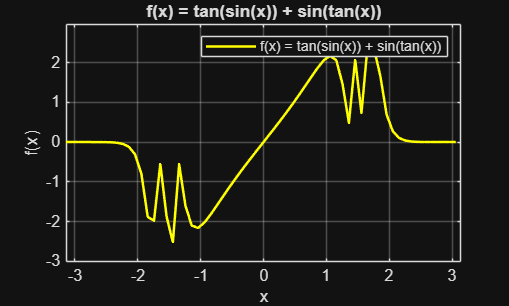

% 2026-09-28
% 3 laboratorinis darbas, privaloma uzduotis
% Jokubas Bridikis

clc; clear; close all;

x = -pi:0.1:pi;
f1 = tan(sin(x)) + sin(tan(x));

figure(1)
plot(x, f1, 'y', 'LineWidth', 1.5)
axis([-pi pi min(f1)-0.5 max(f1)+0.5])
grid on
title('f(x) = tan(sin(x)) + sin(tan(x))')
xlabel('x')
ylabel('f(x)')
legend('f(x) = tan(sin(x)) + sin(tan(x))')

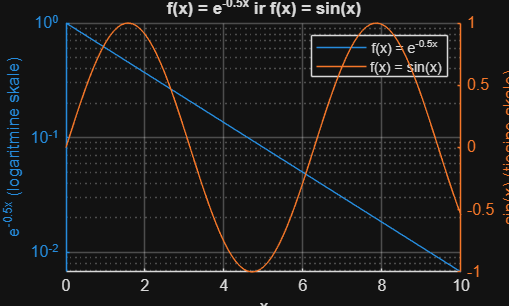


x2 = 0:0.1:10;
f2 = exp(-0.5*x2);
f3 = sin(x2);

figure(2)
[ax, h1, h2] = plotyy(x2, f2, x2, f3, 'semilogy', 'plot');
grid on
title('f(x) = e^{-0.5x} ir f(x) = sin(x)')
xlabel('x')
ylabel(ax(1), 'e^{-0.5x} (logaritmine skale)')
ylabel(ax(2), 'sin(x) (tiesine skale)')
legend([h1 h2], 'f(x) = e^{-0.5x}', 'f(x) = sin(x)')

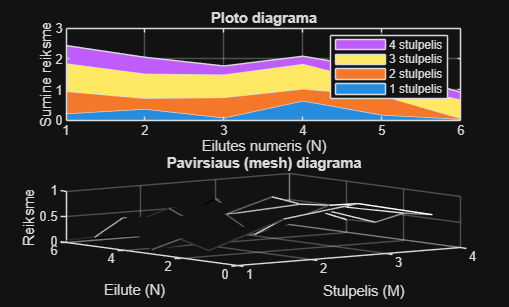


N = 6;
M = 4;
Z = rand(N, M);

figure(3)
subplot(2, 1, 1)
area(Z)
colormap(gray)
grid on
title('Ploto diagrama')
xlabel('Eilutes numeris (N)')
ylabel('Sumine reiksme')
legend('1 stulpelis', '2 stulpelis', '3 stulpelis', '4 stulpelis')

subplot(2, 1, 2)
mesh(Z)
colormap(gray)
title('Pavirsiaus (mesh) diagrama')
xlabel('Stulpelis (M)')
ylabel('Eilute (N)')
zlabel('Reiksme')